# Longitudinal Vehicle

## Varying Road Grade

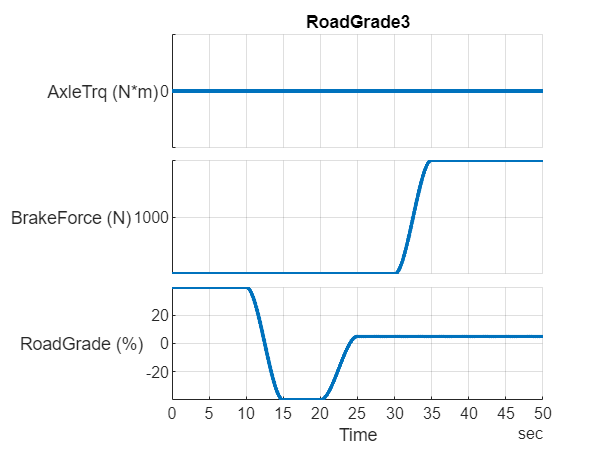

mdl = "Vehicle1D_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

Vehicle1D_harness_setup

vehSigBuilder = Vehicle1D_InputSignalBuilder("Plot_tf",true);

inpData = RoadGrade3(vehSigBuilder);

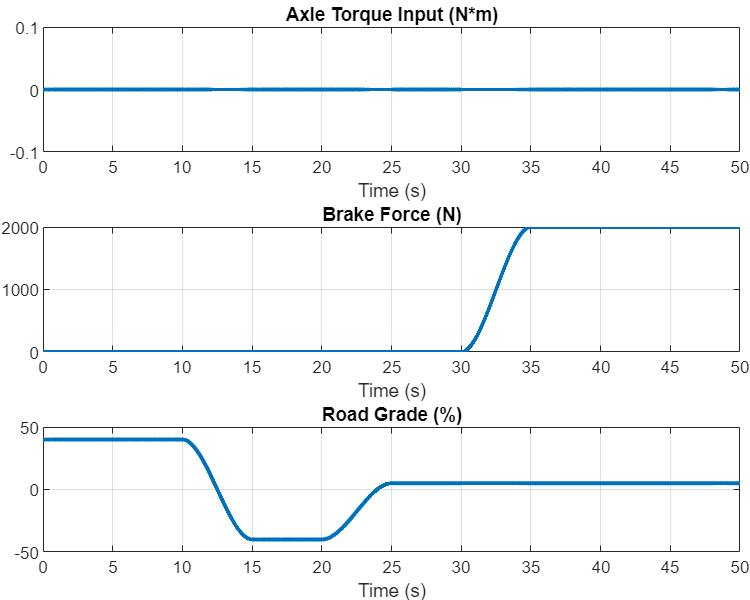

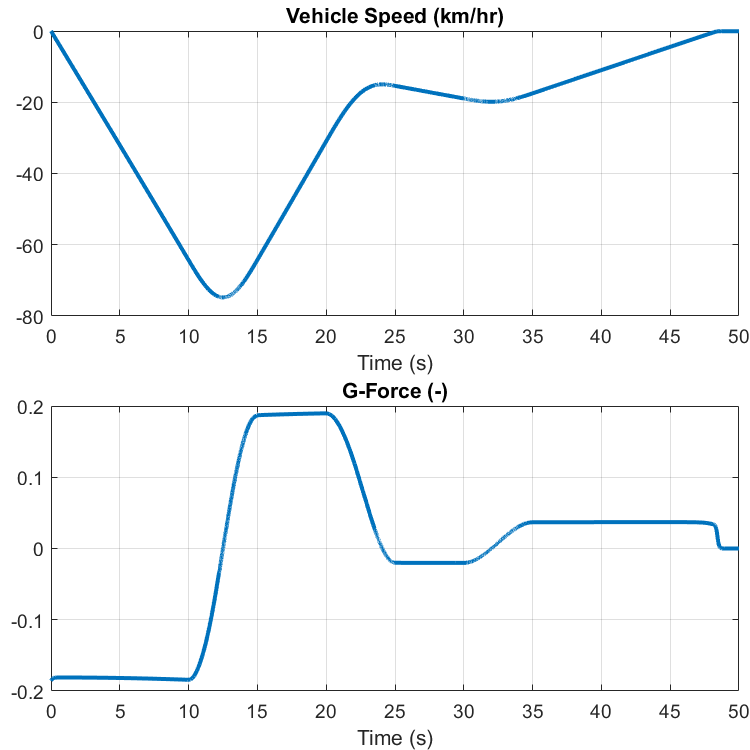

simIn = Simulink.SimulationInput(mdl);
simIn = setVariable(simIn, "vehicle_InputSignals", inpData.Signals);
simIn = setVariable(simIn, "vehicle_InputBus", inpData.Bus);
simIn = setModelParameter(simIn, "StopTime",num2str(inpData.Options.StopTime_s));

simOut = sim(simIn);

Vehicle1D_plot_results(simOut.logsout);

*Copyright 2020-2022 The Mathworks, Inc.*